# Math 503B Homework 5 Ashley Jubb

For the seismic voltage output example with two pulses m_true= e^ - (t -8)^2/(2*sigma_m^2)+ 0.5*e^ -(t-25)^2/(2*sigma_m^2) and the noisy data, plot  m_alpha and m_true together for varying alpha Visually find a good alpha.

% make sure we have a clean environment
clear
rand('seed',0);
randn('seed',0);

% Find G matrix 
sigma=2;
t=linspace(-5,100,211);
mTrue=exp(-((t-8).^2/(2*sigma.^2))+0.5*exp(-((t-25).^2)/(2*sigma.^2)));
G=zeros(length(t), length(t));
for i=1:length(G)-1;
    delt=t(i+1)-t(i);
    for j=1:length(G)-1;
        if i>=j;
            G(i,j)= mTrue(i)*delt;
        else
            G(i,j)=0;
        end
    end
end
n=length(t);
dspiken= mTrue*G';
mNoise=mTrue+ randn*mTrue;

% Calculate the svd
[U,S,V]=svd(G);
s=diag(S);
alpha_min=min(s);
alpha_max=max(s);

[rho,eta,reg_param]=l_curve_tikh_svd(U,s,dspiken',n);

% estimate the L-curve corner in log-log space using a spline fit to find where
% maximum negative curvature occurs(requires Spline Toolbox)
[alpha_tikh,ireg_corner] = l_curve_corner(rho,eta,reg_param);
rho_corner=rho(ireg_corner);
eta_corner=eta(ireg_corner);
disp(['alpha from L curve corner is ', num2str(alpha_tikh)]);

alpha from L curve corner is 6.7238


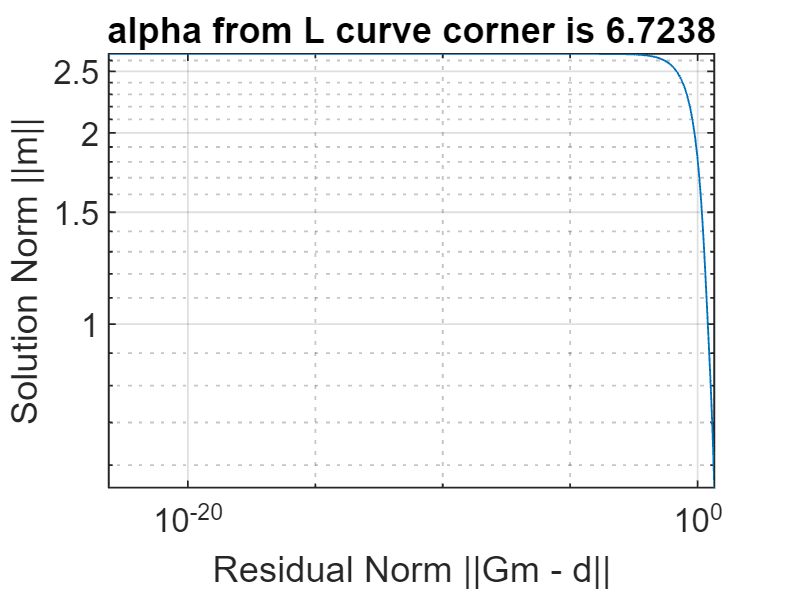


figure(); clf;
loglog(rho,eta); grid on;
xlabel('Residual Norm ||Gm - d||')
ylabel('Solution Norm ||m||')

% estimate the L-curve corner in log-log space using a spline fit 
% to find where maximum negative curvature occurs(requires Spline Toolbox)
[alpha_tikh,ireg_corner] = l_curve_corner(rho,eta,reg_param);
rho_corner = rho(ireg_corner);
eta_corner = eta(ireg_corner);
title(['alpha from L curve corner is ', num2str(alpha_tikh)]);

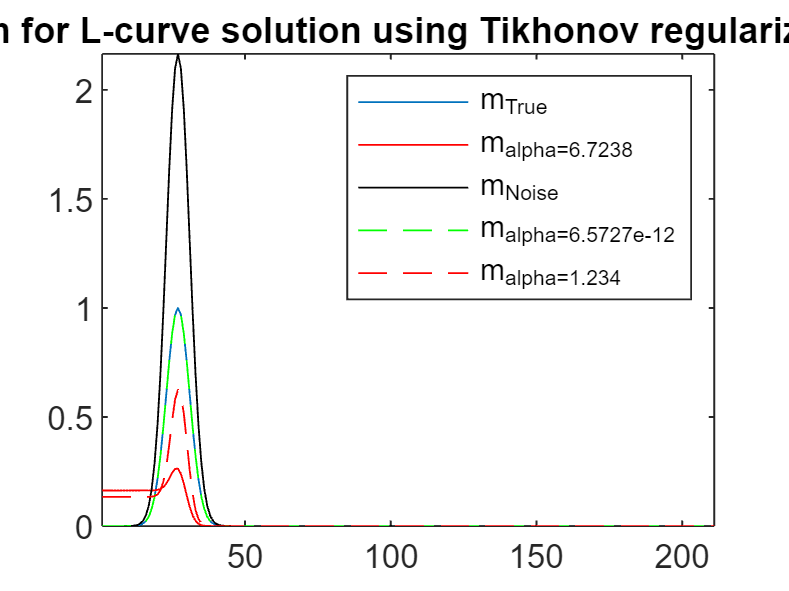


% Compute the Tikhonov Regularization solution
% get the spike solution corresponding to the L-curve corner
G_tikh = G'*G+alpha_tikh*(1+.05*randn*sigma).^2*eye(n);
m_tikh = (G_tikh)\G'*dspiken';

%Compute Tikhonov solution using different alphas
G_tikh2 = G'*G+6.5727e-12*(1+.05*randn*sigma).^2*eye(n);
m_tikh2 = (G_tikh2)\G'*dspiken';
G_tikh3 = G'*G+1.234*(1+.05*randn*sigma).^2*eye(n);
m_tikh3 = (G_tikh3)\G'*dspiken';


% get and display the residual using the L-curve solution for mtrue, mnoise
% and various values of alpha
r_spike = norm(G*m_tikh-dspiken);
d_tikh = G*m_tikh;
figure(); clf;
plot(mTrue); hold on;
plot(m_tikh,'r');
plot(mNoise,'k');
plot(m_tikh2,'g--');
plot(m_tikh3,'r--');
axis("tight")
legend('m_{True}','m_{alpha=6.7238}','m_{Noise}','m_{alpha=6.5727e-12}','m_{alpha=1.234}')
title(['Residual norm for L-curve solution using Tikhonov regularization: ',num2str(r_spike)]);

## Visually the alpha that provides the best solution is alpha=6.5727e-12.